% Arbeitsbereich und Befehlsfenster löschen
clear;
clc;

% Numerische Werte für die Komponenten definieren (Kapazitäten um den Faktor 100 vergrößert, Widerstände um den Faktor 100 verkleinert)
R1_LP = 8.2e1; % 82 Ohm (ehemals 8,2k Ohm)
C1_LP = 33e-9; % 33nF (ehemals 330pF)

R1_SKLP = 820; % 820 Ohm (ehemals 82k Ohm)
R2_SKLP = 270; % 270 Ohm (ehemals 27k Ohm)
R3_SKLP = 10; % 10 Ohm (ehemals 1k Ohm)
R4_SKLP = 6.8; % 6.8 Ohm (ehemals 680 Ohm)
C1_SKLP = 15e-9; % 15nF (ehemals 150pF)
C2_SKLP = 2.2e-9; % 2.2nF (ehemals 22pF)

C1_HP = 68e-9; % 68nF (ehemals 680pF)
R1_HP = 47; % 47 Ohm (ehemals 4,7k Ohm)

R1_SKHP = 220; % 220 Ohm (ehemals 22k Ohm)
R2_SKHP = 1e3; % 1k Ohm (ehemals 100k Ohm)
R3_SKHP = 10; % 10 Ohm (ehemals 1k Ohm)
R4_SKHP = 6.8; % 6.8 Ohm (ehemals 680 Ohm)
C1_SKHP = 6.8e-9; % 6.8nF (ehemals 68pF)
C2_SKHP = 6.8e-9; % 6.8nF (ehemals 68pF)

% Verstärkungsberechnungen
G_SKLP = (R3_SKLP + R4_SKLP) / R3_SKLP; % Verstärkung für Sallen-Key Tiefpassfilter
G_SKHP = (R3_SKHP + R4_SKHP) / R3_SKHP; % Verstärkung für Sallen-Key Hochpassfilter

% Symbolische Variable für s definieren
syms s

% Übertragungsfunktionen der einzelnen Stufen definieren

% RC Tiefpassfilter
H_LP = (1 / (R1_LP * C1_LP)) / (s + (1 / (R1_LP * C1_LP)));

% Korrigierter Sallen-Key Tiefpassfilter
H_SKLP = (G_SKLP / (C1_SKLP * C2_SKLP * R1_SKLP * R2_SKLP)) / ...
    (s^2 + s * ((1 / (C1_SKLP * R2_SKLP)) + (1 / (C1_SKLP * R1_SKLP)) + (1 / (C2_SKLP * R2_SKLP)) * (1 - G_SKLP)) + ...
    (1 / (C1_SKLP * C2_SKLP * R1_SKLP * R2_SKLP)));

% RC Hochpassfilter
H_HP = (s) / (s + (1 / (R1_HP * C1_HP)));

% Sallen-Key Hochpassfilter
H_SKHP = G_SKHP * s^2 / (s^2 + ...
    s * ((1 / (C1_SKHP * R2_SKHP)) + (1 / (C2_SKHP * R2_SKHP)) + (1 / (C1_SKHP * R1_SKHP)) * (1 - G_SKHP)) + ...
    (1 / (C1_SKHP * C2_SKHP * R1_SKHP * R2_SKHP)));

% Gesamtübertragungsfunktion
H_overall = H_LP * H_SKLP * H_HP * H_SKHP;

% Symbolische Übertragungsfunktion in numerische Übertragungsfunktion umwandeln
[num_overall, den_overall] = numden(H_overall); % Zähler und Nenner erhalten
num_overall = sym2poly(num_overall); % Zähler in Polynomkoeffizienten umwandeln
den_overall = sym2poly(den_overall); % Nenner in Polynomkoeffizienten umwandeln

% Frequenzbereich für die Darstellung definieren
f = logspace(1, 6, 1000); % Frequenzbereich von 10 Hz bis 1 MHz
w = 2*pi*f; % In Winkelgeschwindigkeit umwandeln

% Frequenzgang berechnen
H = freqs(num_overall, den_overall, w);

% Grenzfrequenzen berechnen
fc_LP = 1 / (2 * pi * R1_LP * C1_LP);
fc_SKLP = 1 / (2 * pi * sqrt(R1_SKLP * R2_SKLP * C1_SKLP * C2_SKLP));
fc_HP = 1 / (2 * pi * R1_HP * C1_HP);
fc_SKHP = 1 / (2 * pi * sqrt(R1_SKHP * R2_SKHP * C1_SKHP * C2_SKHP));

% Grenzfrequenzen anzeigen
fprintf('Grenzfrequenz des RC Tiefpassfilters: %.2f Hz\n', fc_LP);

Grenzfrequenz des RC Tiefpassfilters: 58815.57 Hz


fprintf('Grenzfrequenz des Sallen-Key Tiefpassfilters: %.2f Hz\n', fc_SKLP);

Grenzfrequenz des Sallen-Key Tiefpassfilters: 58880.89 Hz


fprintf('Grenzfrequenz des RC Hochpassfilters: %.2f Hz\n', fc_HP);

Grenzfrequenz des RC Hochpassfilters: 49798.17 Hz


fprintf('Grenzfrequenz des Sallen-Key Hochpassfilters: %.2f Hz\n', fc_SKHP);

Grenzfrequenz des Sallen-Key Hochpassfilters: 49899.92 Hz


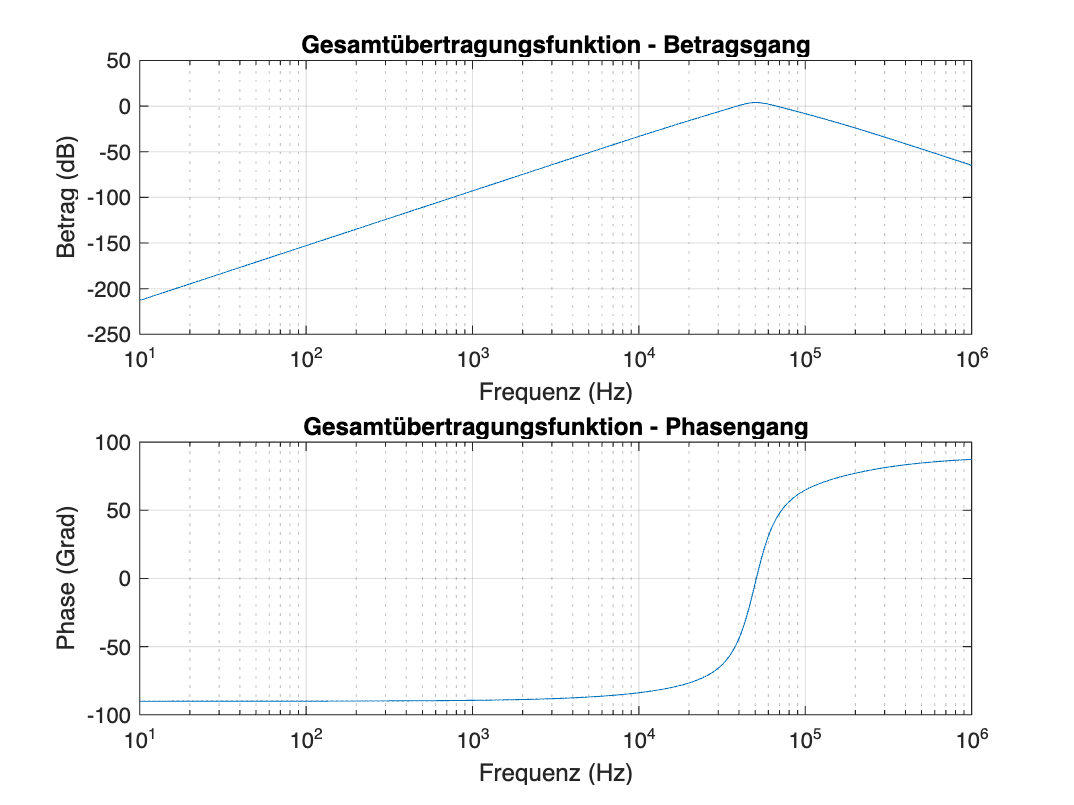


% Betrags- und Phasengang mit Frequenz in Hz darstellen
figure;
subplot(2, 1, 1);
semilogx(f, 20*log10(abs(H)));
grid on;
title('Gesamtübertragungsfunktion - Betragsgang');
xlabel('Frequenz (Hz)');
ylabel('Betrag (dB)');

% Phasengang darstellen
subplot(2, 1, 2);
semilogx(f, angle(H) * 180 / pi);
grid on;
title('Gesamtübertragungsfunktion - Phasengang');
xlabel('Frequenz (Hz)');
ylabel('Phase (Grad)');

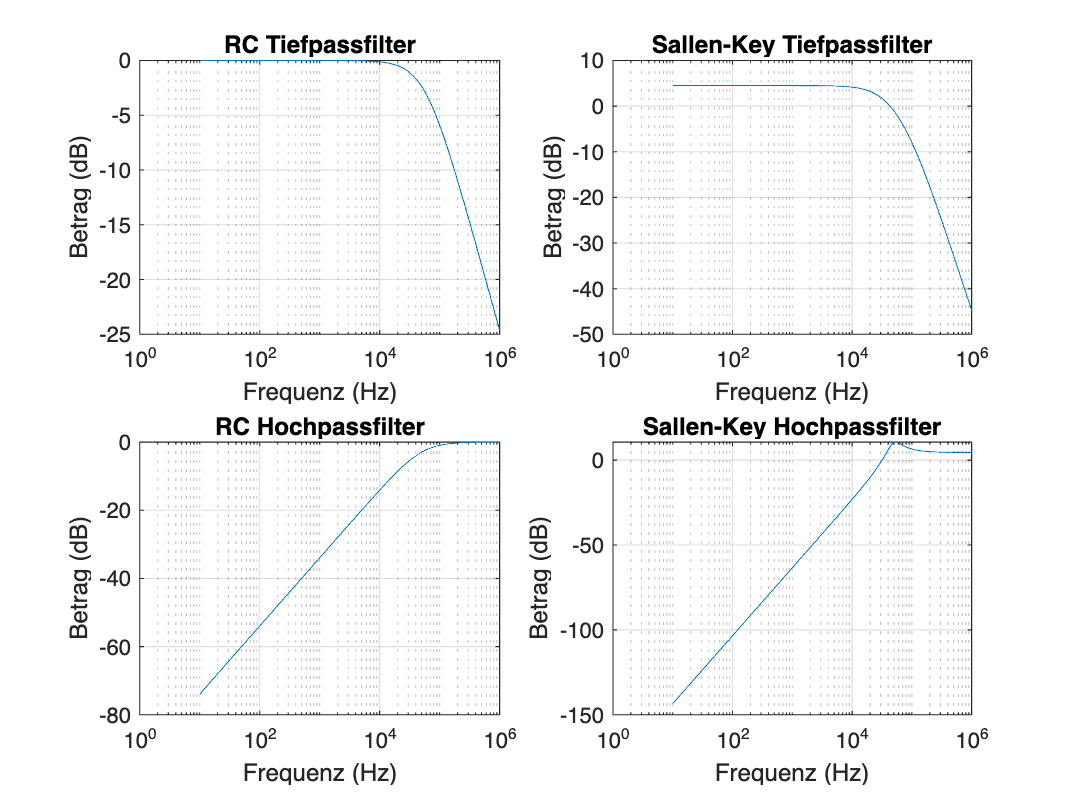


% Einzelne Stufen darstellen
% RC Tiefpassfilter
[num_LP, den_LP] = tfdata(tf((1 / (R1_LP * C1_LP)), [1 (1 / (R1_LP * C1_LP))]), 'v');
H_LP_freq = freqs(num_LP, den_LP, w);

% Sallen-Key Tiefpassfilter
[num_SKLP, den_SKLP] = tfdata(tf((G_SKLP / (C1_SKLP * C2_SKLP * R1_SKLP * R2_SKLP)), ...
    [1 ((1 / (C1_SKLP * R2_SKLP)) + (1 / (C1_SKLP * R1_SKLP)) + (1 / (C2_SKLP * R2_SKLP)) * (1 - G_SKLP)) ...
    (1 / (C1_SKLP * C2_SKLP * R1_SKLP * R2_SKLP))]), 'v');
H_SKLP_freq = freqs(num_SKLP, den_SKLP, w);

% RC Hochpassfilter
[num_HP, den_HP] = tfdata(tf([1 0], [1 (1 / (R1_HP * C1_HP))]), 'v');
H_HP_freq = freqs(num_HP, den_HP, w);

% Sallen-Key Hochpassfilter
[num_SKHP, den_SKHP] = tfdata(tf(G_SKHP * [1 0 0], ...
    [1 ((1 / (C1_SKHP * R2_SKHP)) + (1 / (C2_SKHP * R2_SKHP)) + (1 / (C1_SKHP * R1_SKHP)) * (1 - G_SKHP)) ...
    (1 / (C1_SKHP * C2_SKHP * R1_SKHP * R2_SKHP))]), 'v');
H_SKHP_freq = freqs(num_SKHP, den_SKHP, w);

% Darstellungen der einzelnen Stufen
figure;
subplot(2, 2, 1);
semilogx(f, 20*log10(abs(H_LP_freq)));
grid on;
title('RC Tiefpassfilter');
xlabel('Frequenz (Hz)');
ylabel('Betrag (dB)');

subplot(2, 2, 2);
semilogx(f, 20*log10(abs(H_SKLP_freq)));
grid on;
title('Sallen-Key Tiefpassfilter');
xlabel('Frequenz (Hz)');
ylabel('Betrag (dB)');

subplot(2, 2, 3);
semilogx(f, 20*log10(abs(H_HP_freq)));
grid on;
title('RC Hochpassfilter');
xlabel('Frequenz (Hz)');
ylabel('Betrag (dB)');

subplot(2, 2, 4);
semilogx(f, 20*log10(abs(H_SKHP_freq)));
grid on;
title('Sallen-Key Hochpassfilter');
xlabel('Frequenz (Hz)');
ylabel('Betrag (dB)');


% Informationen über die 3dB-Punkte und Verstärkung
fprintf('Die 3dB-Punkte und die Verstärkung der einzelnen Stufen:\n');

Die 3dB-Punkte und die Verstärkung der einzelnen Stufen:


fprintf('RC Tiefpassfilter: %.2f Hz, Verstärkung: %.2f dB\n', fc_LP, 20*log10(abs(H_LP_freq(find(f >= fc_LP, 1)))));

RC Tiefpassfilter: 58815.57 Hz, Verstärkung: -3.05 dB


fprintf('Sallen-Key Tiefpassfilter: %.2f Hz, Verstärkung: %.2f dB\n', fc_SKLP, 20*log10(abs(H_SKLP_freq(find(f >= fc_SKLP, 1)))));

Sallen-Key Tiefpassfilter: 58880.89 Hz, Verstärkung: -2.45 dB


fprintf('RC Hochpassfilter: %.2f Hz, Verstärkung: %.2f dB\n', fc_HP, 20*log10(abs(H_HP_freq(find(f >= fc_HP, 1)))));

RC Hochpassfilter: 49798.17 Hz, Verstärkung: -3.00 dB


fprintf('Sallen-Key Hochpassfilter: %.2f Hz, Verstärkung: %.2f dB\n', fc_SKHP, 20*log10(abs(H_SKHP_freq(find(f >= fc_SKHP, 1)))));

Sallen-Key Hochpassfilter: 49899.92 Hz, Verstärkung: 10.34 dB
